# No Load Motor Experiments

k = 20;

rpms{k} = [];
curs{k} = [];
thrs{k} = [];
trqs{k} = [];
mval{k} = [];

motorRes = [.4 .4 .4 .4];
tic
for i = 1:k
    sim('newBLDCmodel_oct1.slx'); 
    rpms{i} = rpm.Data;
    curs{i} = i_mot.Data;
    thrs{i} = th_mot.Data;
    trqs{i} = tq_mot.Data;
    mval{i} = motorRes(1);
    motorRes(1) = motorRes(1) + .005;
    %clear rpm i_mot th_mot tq_mot;
end
toc
labels{k} = [];
f5 = figure(5); clf;
hold on;
for i = 1:k
    plot(i, mval{1,i}, 'o');
    labels{i} = "R: " + num2str(mval{1,i}) + "{\Omega}";
end
hold off;
ylim([.2 .6]);
legend(labels, 'Location', 'southeast');
title("Motor 1 Resistance Values");
xlabel("Run Number");
ylabel("Resistance ({\Omega})");
f6 = figure(6); clf;
hold on;
for i = 1:k
    plot(i, curs{i}(end), 'o');
end
hold off;
title("Steady State Current Draw");
xlabel("Run Number");
ylabel("Current (A)");
legend(labels);
f7 = figure(7); clf;
hold on;
for i = 1:k
    plot(i, rpms{i}(end), 'o');
end
hold off;
title("Steady State RPM");
xlabel("Run Number");
ylabel("RPM");
legend(labels);
f8 = figure(8); clf;
hold on;
for i = 1:k
    plot(i, trqs{i}(end), 'o');
end
hold off;
title("Steady State Torque");
xlabel("Run Number");
ylabel("Torque (N-m)");
legend(labels);
f9 = figure(9); clf;
hold on;
for i = 1:k
    plot(i, thrs{i}(end), 'o');
end
hold off;
title("Steady State Thrust");
xlabel("Run Number");
ylabel("Thrust (N)");
legend(labels);
f10 = figure(10); clf;
hold on;
for i = 1:k
    plot(rpms{i});
end
hold off;
title("RPM Arrays");
f11 = figure(11); clf;
hold on;
for i = 1:k
    plot(curs{i});
end
hold off;
title("Current Arrays");
f12 = figure(12); clf;
hold on;
for i = 1:k
    plot(trqs{i});
end
hold off;
title("Torque Arrays");
f13 = figure(13); clf;
hold on;
for i = 1:k
    plot(thrs{i});
end
hold off;
title("Thrust Arrays");

f1 = figure(1); clf;
hold on;
plot(rpm_hat.Time, rpm_hat.Data, 'g');
plot(rpm.Time, rpm.Data, 'b', 'linewidth', 2);
hold off;
xlabel("Time (s)");
ylabel("RPM");
title("Single Motor RPM");
legend(["Estimated RPM", "Actual RPM"]);
rpm_res_ss = rpm_res.Data(:,:)';
disp("steady state rpm residual: " + num2str(mean(rpm_res_ss(length(rpm_res_ss)/2:end)/100)));
i_hatData = i_hat.Data(1,:);
f2 = figure(2); clf;
hold on;
plot(i_hat.Time, i_hatData, 'g');
plot(i_mot.Time, i_mot.Data, 'b', 'linewidth', 2);
hold off;
% title("Single Motor Current Draw");
xlabel("Time (s)");
ylabel("Current (A)");
legend(["Estimated Current", "Actual Current: " + num2str(i_mot.Data(1000))]);
ylim([0 4]);
i_res_ss = i_res.Data(:,:)';
disp("steady state current residual: " + num2str(mean(i_res_ss(length(i_res_ss)/2:end)/100)));
f3 = figure(3); clf;
plot(th_mot);

f4 = figure(4); clf;
plot(tq_mot);

# Prognostic Experiment

warning('off','MATLAB:polyfit:RepeatedPointsOrRescale');

k = 1000;
motorRes = [.4 .4 .4 .4];

rpms = zeros(1,k);
curs = zeros(1,k);
trqs = zeros(1,k);
mval = zeros(1,k);

setRPM = 6700;

eol = 266; % cycle 266

RPMe = rpms;
RPMpreds = rpms;

maintWarn   = 0;
maintNotice = false;
failWarn    = 0;
failNotice  = false;

maintThresh = setRPM * .95;
failThresh = setRPM * .9;

maintFlag = false;
failFlag  = false;
time = 0;
tic
for i = 1:k
    sim('newBLDCmodel_oct1.slx'); 
    rpms(i) = rpm.Data(end);
    curs(i) = i_mot.Data(end);
    trqs(i) = tq_mot.Data(end);
    mval(i) = motorRes(1);
    motorRes(1) = motorRes(1) + .001;
    RPMe(i) = normrnd(rpms(i), 30);
    time = time + tout(end);
    
    if i >= 20
        x = (i-19):1:i;
        p_rpm = polyfit(x, smoothdata(RPMe((i-19):i), 'rlowess', 15), 1);
        
        rpm_pred = polyval(p_rpm, i+20);
        
        RPMpreds(i) = polyval(p_rpm, i+5);
        
        if ~maintFlag && rpm_pred <= maintThresh
            maintFlag = true;
            maintWarn = i;
            disp(["Maintenance threshold will be reached at cycle: "  num2str(i+20)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~maintNotice && RPMpreds(i) >= .985*maintThresh && RPMpreds(i) <= 1.015*maintThresh
            maintNotice = true;
            disp(["Maintenance Required. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if ~failFlag && rpm_pred <= failThresh
            failFlag = true;
            failWarn = i;
            disp(["Failure threshold will be reached at cycle: "  num2str(i+20)  "."]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]); 
        end
        
        if ~failNotice && RPMpreds(i) >= .995*failThresh && RPMpreds(i) <= 1.015*failThresh
            failNotice = true;
            disp(["Estimated failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
        end
        
        if rpms(i) <= failThresh
            disp(["Actual failure is reached. Current cycle: " num2str(i)]);
            disp(["Cumulative flight hours: "  num2str(time/60/60)]);
            eol = i;
            break
        end
    end
end

    "Maintenance Required. Current cycle: "    "107"



    "Cumulative flight hours: "    "5.9444"



    "Maintenance threshold will be reached at …"    "129"    "."



    "Cumulative flight hours: "    "6.0556"



    "Estimated failure is reached. Current cycle: "    "286"



    "Cumulative flight hours: "    "15.8889"



    "Failure threshold will be reached at cycl…"    "333"    "."



    "Cumulative flight hours: "    "17.3889"



    "Actual failure is reached. Current cycle: "    "350"



    "Cumulative flight hours: "    "19.4444"



toc

Elapsed time is 866.111317 seconds.


motorResults.setRPM = setRPM;
motorResults.failThresh = failThresh;
motorResults.failWarn = failWarn;
motorResults.rpms = rpms;
motorResults.mvals = mval;
motorResults.RPMe = RPMe;
motorResults.RPMpreds = RPMpreds;
motorResults.eol = eol;
motorResults.maintWarn = maintWarn;
motorResults.maintThresh = maintThresh;
motorResults.pgon = pgon;

save('motorResults.mat', 'motorResults');


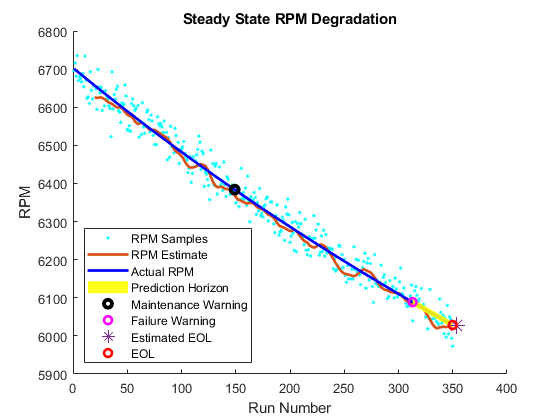

f15 = figure(15); clf;
hold on;
% for i = 1:k
%     if i == failWarn
%         break;
%     end
%     plot(i, rpms(i), 'b.');
% end
plot(RPMe(1:eol), 'c.');
plot([20:1:eol]',smoothdata(RPMpreds(20:eol), 'movmean', 15), 'linew', 2);
plot(rpms(1:eol), 'b', 'linew', 2);
pgon = polyshape([failWarn failWarn eol eol], [rpms(failWarn)-8 rpms(failWarn)+8 rpms(eol)+8 rpms(eol)-8]);
plot(pgon, 'FaceColor', 'yellow', 'FaceAlpha', .89, 'EdgeColor', 'none');
plot(maintWarn+40, rpms(maintWarn+40), 'ko', 'linew', 3);
plot(failWarn, rpms(failWarn), 'mo', 'linew', 2);
plot(failWarn+40, rpms(failWarn+37), '*', 'MarkerSize', 12);
plot(eol, rpms(eol), 'ro', 'linew', 2);
hold off;
title("Steady State RPM Degradation");
xlabel("Run Number");
ylabel("RPM");
legend(["RPM Samples", "RPM Estimate", "Actual RPM", "Prediction Horizon", "Maintenance Warning", "Failure Warning", "Estimated EOL", "EOL"], 'location', 'southwest');